%pkg load 'linear-algebra'
% Read the image into A as a matrix of uint8
[X,map] = imread('witchhead.jpg');
% Display the image as Figure 1
%image(A)
% Subtract 100 from each value in A and store the result in B
%B = A - 100;
%C = A.';
%image(C)
%image(B)
Im = X;
if ~isempty(map)
    Im = ind2rgb(X,map);
    [U,S,V] = svd(Im);
end
% Convert image from uint8 to doubles for svd
X = im2double(X);

[U_r,S_r,V_r] = svd(X(:,:,1));
[U_g,S_g,V_g] = svd(X(:,:,2));
[U_b,S_b,V_b] = svd(X(:,:,3));


%confirmation checking for red
out_red = U_r*S_r*V_r'

out_red =     0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0588    0.0588    0.0588    0.0549    0.0549    0.0510    0.0510    0.0510    0.0510    0.0510
    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0588    0.0588    0.0588    0.0549    0.0549    0.0510    0.0510    0.0510    0.051

red = X(:,:,1)

red =     0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0588    0.0588    0.0588    0.0549    0.0549    0.0510    0.0510    0.0510    0.0510    0.0510
    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0353    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0549    0.0588    0.0588    0.0588    0.0549    0.0549    0.0510    0.0510    0.0510    0.0510   


% S_r has size 640x1138, thus 640 diagonal values
size(S_r)

ans =          640        1138


% Find the largest k singular values
k = 30;
redk = zeros(k,1);
greenk = zeros(k,1);
bluek = zeros(k,1);

% Discovered that the diagonal of the sum matrix is in order
for i = 1:k
    redk(i) = S_r(i,i);
    greenk(i) = S_g(i,i);
    bluek(i) = S_b(i,i);
end


% Storage Analysis
initialStorage = 640*1138

initialStorage = 728320

currentStorage = (640+1138)*k+k

currentStorage = 53370

% Error Analysis
sume = 0;
for i = 1:640
    sume = sume + S_r(i,i) + S_g(i,i) + S_b(i,i);
end
error = sum(redk+greenk+bluek) / sume

error = 0.6752

NewImage_r = zeros(640,1138);
NewImage_g = zeros(640,1138);
NewImage_b = zeros(640,1138);
for i = 1:k
    NewImage_r = NewImage_r + redk(i)* U_r(:,i)*V_r(:,i)';
    NewImage_g = NewImage_g + greenk(i) * U_g(:,i)*V_g(:,i)';
    NewImage_b = NewImage_b + bluek(i) * U_b(:,i)*V_b(:,i)';
end


% Normalize the matrices to fit the rgb format
for i = 1:640
    for j = 1:1138
        if(NewImage_r(i,j) < 0)
            NewImage_r(i,j) = 0;
        end
        if(NewImage_g(i,j) < 0)
            NewImage_g(i,j) = 0;
        end
        if(NewImage_b(i,j) < 0)
            NewImage_b(i,j) = 0;
        end
    end
end

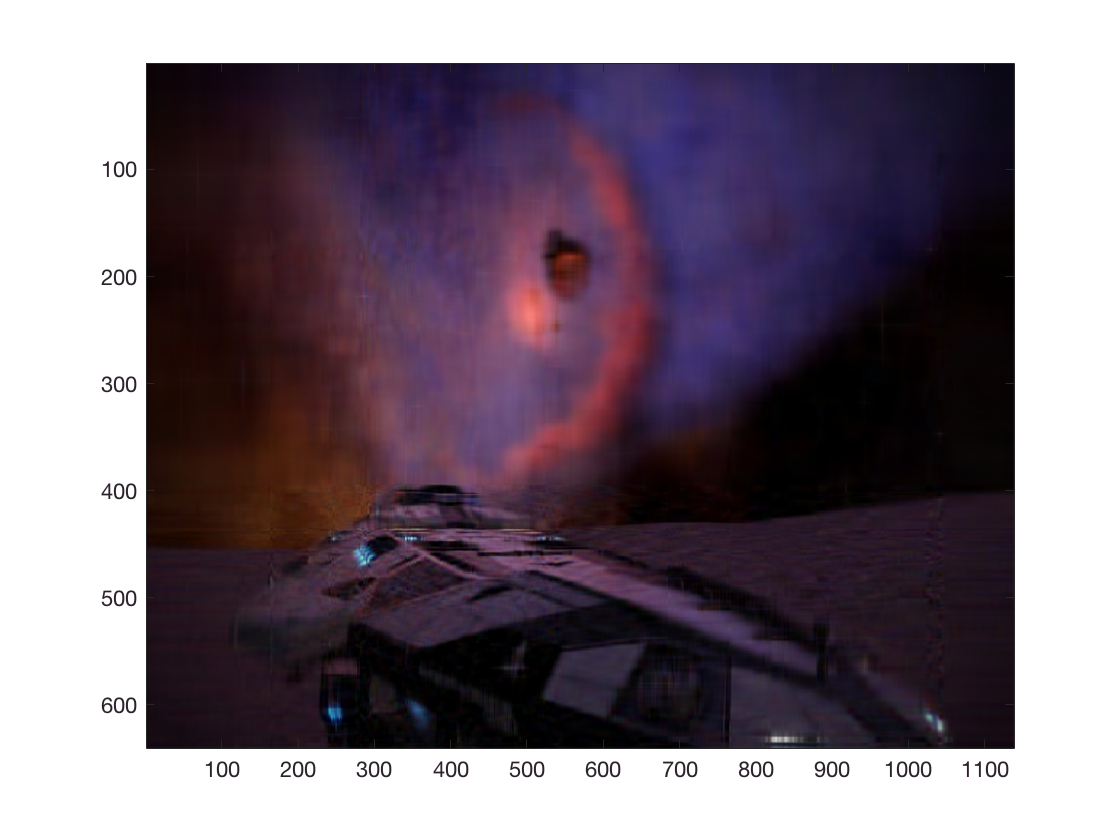

rgbImage = cat(3, NewImage_r, NewImage_g, NewImage_b);
image(rgbImage)

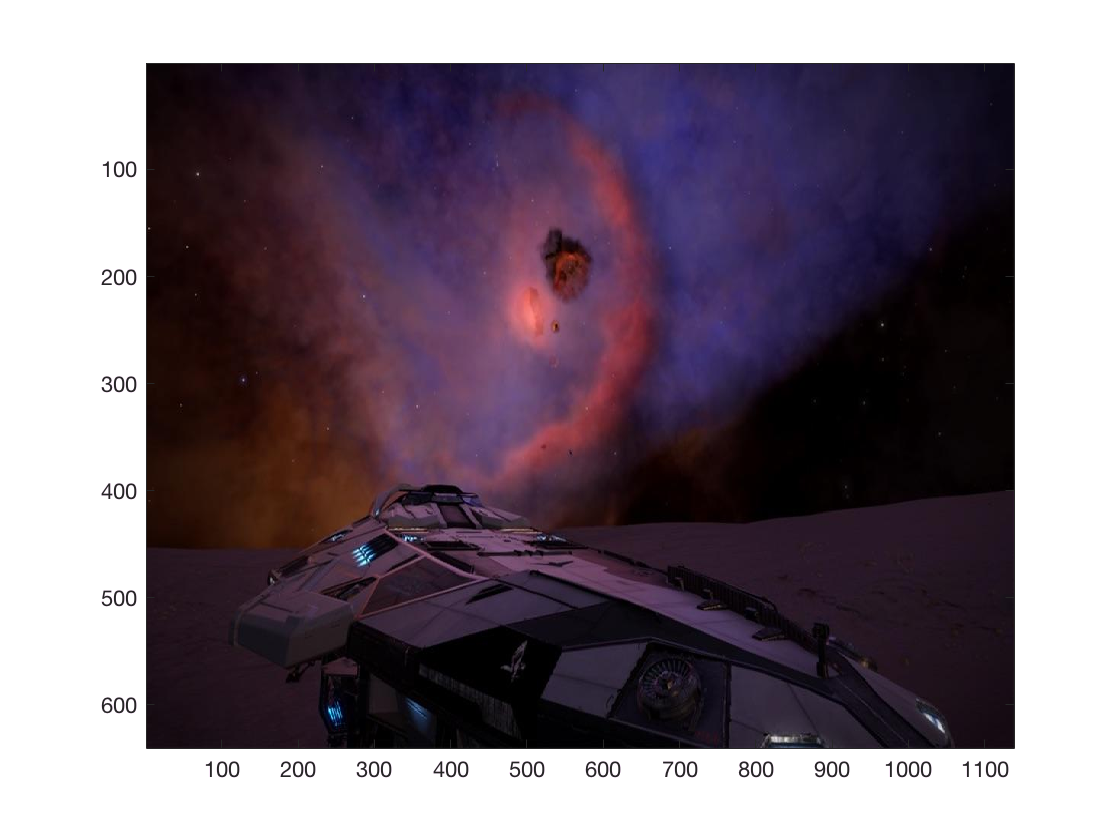

image(X)

difference = rgbImage-X

difference = 
(:,:,1) =

  1 至 999 列

    0.0096    0.0107    0.0103    0.0082    0.0076    0.0091    0.0103    0.0101    0.0095    0.0096    0.0100    0.0107    0.0110    0.0117    0.0119    0.0121    0.0094    0.0092    0.0095    0.0095    0.0097    0.0097    0.0099    0.0098    0.0087    0.0085    0.0085    0.0079    0.0081    0.0077    0.0079    0.0079   -0.0051   -0.0052   -0.0052   -0.0055   -0.0058   -0.0062   -0.0065   -0.0067   -0.0095   -0.0094   -0.0094   -0.0050   -0.0044    0.0002   -0.0000   -0.0005    0.0013    0.0015    0.0021   -0.0015   -0.0010    0.0011   -0.0020   -0.0035   -0.0031   -0.0033   -0.0034   -0.0072   -0.0071   -0.0107   -0.0104   -0.0101   -0.0124   -0.0117   -0.0133   -0.0140   -0.0141   -0.0149   -0.0147   -0.0152   -0.0247   -0.0247   -0.0245   -0.0254   -0.0252   -0.0261   -0.0263   -0.0266   -0.0204   -0.0207   -0.0202   -0.0202   -0.0199   -0.0197   -0.0195   -0.0197   -0.0228   -0.0229   -0.0227   -0.0227   -0.0224   -0.0223   -0.0220   -0.0216  

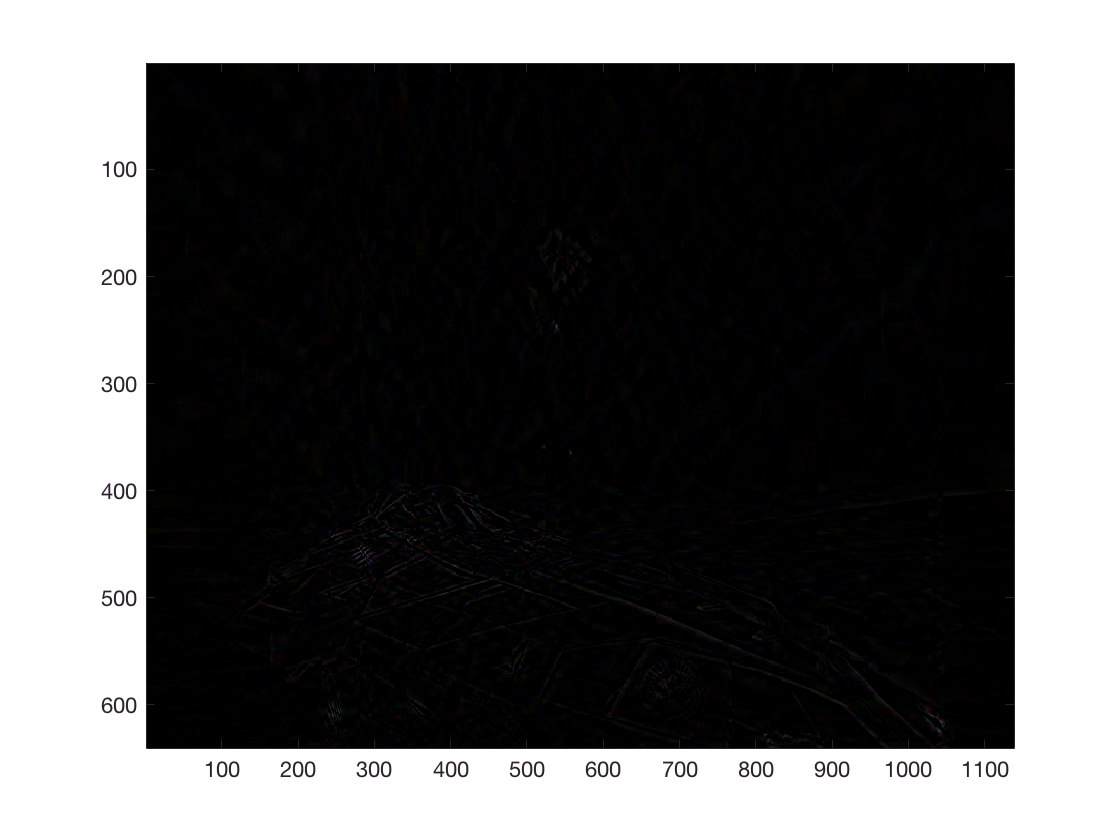

image(rgbImage-X)